% %curve fitting
% data = xlsread('附件1.xlsx');
% t=data(:,1);
% u=(data(:,2)+273.15);
% [fitresult, ~]=createFit(t,u);

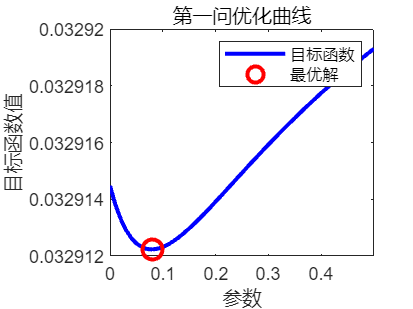

clc,clear
%优化
x_lb=0;
x_ub=0.5;
param_range = x_lb:0.01:x_ub;
%计算目标函数值
objective_values = zeros(size(param_range));
for i = 1:length(param_range)
    objective_values(i) = Obj_fun(param_range(i));
end
%绘制曲线
plot(param_range, objective_values, 'b-', 'LineWidth', 2);
hold on;
[best_value, best_index] = min(objective_values);
best_param = param_range(best_index);
plot(best_param, best_value, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
title('第一问优化曲线');
xlabel('参数');
ylabel('目标函数值');
legend('目标函数', '最优解');

% %粒子群算法
narvs=1;
%options = optimoptions('particleswarm','HybridFcn',@fmincon);
options = optimoptions('particleswarm','PlotFcn','pswplotbestf','Display','iter') 

options =   particleswarm 选项:

   设置属性:
                   Display: 'iter'
                   PlotFcn: 'pswplotbestf'

   默认属性:
               CreationFcn: @pswcreationuniform
         FunctionTolerance: 1.0000e-06
                 HybridFcn: []
              InertiaRange: [0.1000 1.1000]
        InitialSwarmMatrix: []
          InitialSwarmSpan: 2000
             MaxIterations: '200*numberofvariables'
        MaxStallIterations: 20
              MaxStallTime: Inf
                   MaxTime: Inf
      MinNeighborsFraction: 0.2500
            ObjectiveLimit: -Inf
                 OutputFcn: []
      SelfAdjustmentWeight: 1.4900
    SocialAdjustmentWeight: 1.4900
                 SwarmSize: 'min(100,10*numberofvariables)'
               UseParallel: 0
             UseVectorized: 0



                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              10         0.03291         0.03292        0
    1              20         0.03291         0.03292        0
    2              30         0.03291         0.03291        0
    3              40         0.03291         0.03291        0
    4              50         0.03291         0.03291        0
    5              60         0.03291         0.03291        1
    6              70         0.03291         0.03291        2
    7              80         0.03291         0.03291        3
    8              90         0.03291         0.03291        4
    9             100         0.03291         0.03291        5
   10             110         0.03291         0.03291        6
   11             120         0.03291         0.03291        7
   12             130         0.03291         0.03291        8
   13             140         0.03291         0.

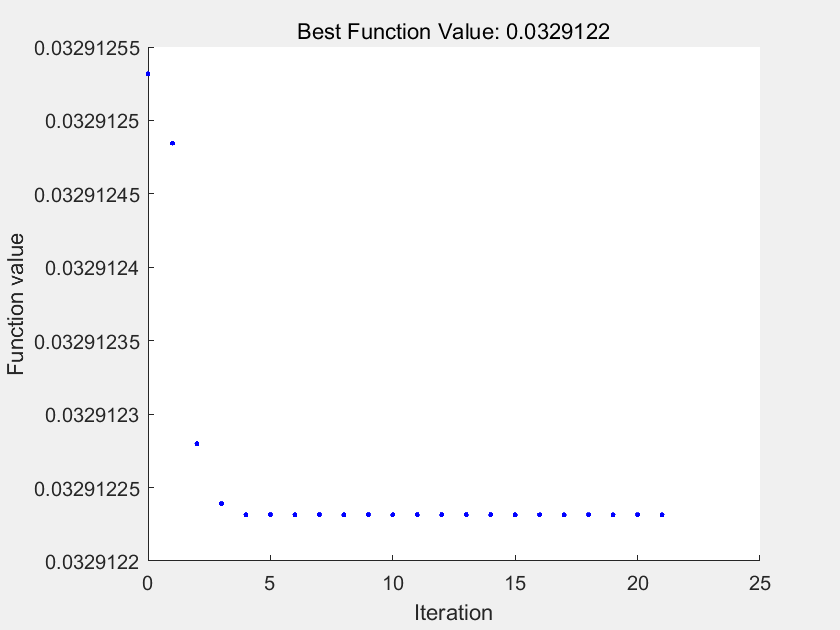

x = 0.0787

fval = 0.0329

exitflag = 1

output = 包含以下字段的 struct :
      rngstate: [1×1 struct]
    iterations: 21
     funccount: 220
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'
    hybridflag: []


[x,fval,exitflag,output] = particleswarm(@Obj_fun, narvs, x_lb, x_ub,options) 

function f=Obj_fun(k_fiber)
    %initialize parameter
    % delta_t=0.0992;         
    % delta_T = 0.9709;          
    % A=a*b;                      %d 单位 mm^2    
    k_tol=0.033;                %热导率 W/(m·K)
    % dx=(x(2)-x(1));             %单位mm
    k_air=0.0296;
    %k_fiber=0.13;
    d=0.6;                      %单根纤维的直径  mm 
    h=2*d;                      %织物的厚度  mm
    rho_s=0.6;                  %经密6/10mm
    rho_w=0.8;                  %维密8/10mm
    a=1/rho_s;                  %经向长度mm
    b=1/rho_w;                  %纬向长度mm
    T_end=0.1;             
    m = 0;
    x = linspace(0,h,50);       %单位 mm
    dx=x(2)-x(1);
    dt=0.01;
    t =0:dt:T_end;               %单位s
    sol = pdepe(m,@(x,t,u,dudt)pdex1pde(x,t,u,dudt,k_fiber),@pdex1ic,@pdex1bc,x,t);
    u = sol(:,:,1);
    %f=sum(abs(u(:,1)'-L_Tight(t)));
    dudx=diff(u(:,1:2),1,2)/dx;
    dudx=gradient(u(:,1:2),dx);
    J=trapz(1e-3*k_air*dudx(:,1),t);
    %k2=abs(J)*dx/dt*abs(u(end,2)-u(end,1));
    k=abs(J)*h/dt/abs(u(end,1)-u(end,end));
    f=abs(k-k_tol);
    % index=[0,0.02,0.04,0.06,0.08,0.1]/dt+1; 
    % T=u(index,1);
    % T_e=[25;25.5751;25.6930;25.8069;25.8960;25.9709]+273.15;
    % f=sum(abs(T-T_e));
    % surf(x,t,u)
    % title('Numerical solution computed with 20 mesh points.')
    % xlabel('Distance x')
    % ylabel('Time t')
    % zlabel('Temperature u')
    % hold off.
end
function [c,f,s] = pdex1pde(x,t,u,dudx,k_fiber)
    cp=0.05;                               %单位  Mj/m^3·K
    %k_tol=0.033;                            %热导率 W/(m·K)
    %alpha_tol=k_tol/cp;                   %总密度  W/(m·K)   mm^2/s   
    k_air=0.0296;                         %单位 W/(m·K)
    d=0.6;
    theta_s=19.8/360*2*pi;                 %经纱弯曲角度 rad
    theta_w=25.64/360*2*pi;                %纬纱弯曲角度 rad
    %1/rho_s*tan(theta_s)=d;
    %1/rho_w*tan(theta_w)=d;
    a=10/6;  %1/rho_s  
    b=10/8; %1/rho_w
    S=a*b; %单位 mm^2
    S2=ca_S(x,d,theta_s,theta_w);
    S1=S-S2;
    k_tol=(S1*k_air+S2*k_fiber)/S;             %截面热导率
    c=cp;
    f =k_tol*dudx;
    s=0;
end
function S=ca_S(h,d,theta_s,theta_w)
    if h>d
        h=1.2-h;
    end   
    l=sqrt((d/2)^2-(d/2-h)^2);           %弦长
    thetas=asin(l/(d/2));
    S_s=pi*(d/2)^2*thetas/2/pi;
    thetaw=asin(l/(d/2));
    S_w=pi*(d/2)^2*thetaw/2/pi;
    S=2*(S_w/tan(theta_w)+S_s/tan(theta_s));
end
function u0 = pdex1ic(x)
    u0 = 298.15;
end
function [pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t)   
    d=0.6;
    %k_tol=;             
    %dt=0.099165;
    dT=0.9708905105832;
    pl=(0.033*dT)/(2*d);
    %pl = 1/A;   
    ql =0.0296;
    %pl=ul-L_Tight(t);
    %ql=0;
    pr = 0;
    qr = 1;
end
function u=L_Tight(t)
  p=[-59599.9047557005	14375.0113350970	-1218.80638780507	47.3729535516151	298.152007531907];
  u = p(1).*t.^4 + p(2).*t.^3 + p(3).*t.^2 + p(4).*t + p(5);
end